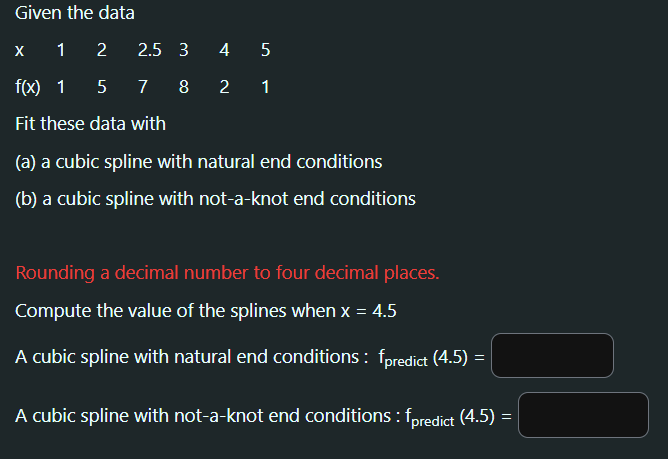

Data 

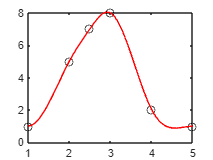

x = [1 2 2.5 3 4 5];
y = [1 5 7 8 2 1];

plot(x,y,'ko')
hold on

A cubic spline with natural end conditions

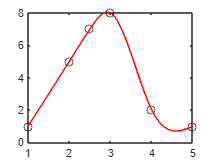

% Given data points
x = [1, 2, 2.5, 3, 4, 5];
y = [1, 5, 7, 8, 2, 1];

% Define the points at which you want to interpolate
xx = 1 : 0.1 : 5;

% Generate the interpolated values using cubic spline with natural end conditions
pp = csape(x, y, 'variational', 'second'); % 'variational' option enforces natural end conditions
yy = ppval(pp, xx); % Evaluate the spline at specified points

% Plot the original data points
figure
plot(x, y, 'ko')
hold on

% Plot the interpolated spline
plot(xx, yy, 'r-')
hold off


x_test = 4.5;
y_pred = ppval(pp,x_test)

y_pred = 0.7189

A cubic spline with not-a-knot end conditions

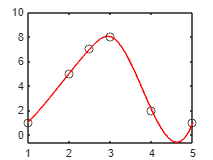

% Given data points
x = [1, 2, 2.5, 3, 4, 5];
y = [1, 5, 7, 8, 2, 1];

% Define the points at which you want to interpolate
xx = 1 : 0.1 : 5;

% Generate the interpolated values using cubic spline with natural end conditions
pp = csape(x, y, 'not-a-knot'); % 'variational' option enforces natural end conditions
yy = ppval(pp, xx); % Evaluate the spline at specified points

% Plot the original data points
figure
plot(x, y, 'ko')
hold on

% Plot the interpolated spline
plot(xx, yy, 'r-')
hold off


x_test = 4.5;
y_pred = ppval(pp,x_test)

y_pred = -0.5255